Right, so, firstly, using Poiseuille's law, $Q=\frac{\Delta p\pi D^4 }{128\mu \;L}$.

Secondly, ideal gas equation $\textrm{PV}=\textrm{mRT}$. Similarly, $P=\rho \text{ }\mathrm{RT}\to \rho =\frac{P}{\mathrm{RT}}=\frac{V}{m}$.

The volume of the cylinder changes as a function of time. Being a single-inlet system, the mass is also a function of time and the system is transient.

So, let $V\left(t\right)$ and $m\left(t\right)$be a function of time and the process be isothermal, then pressure inside the cylinder is given by ideal gas equation $P\left(t\right)=m\left(t\right)\frac{\textrm{RT}}{V\left(t\right)}$.

Identifying the system as a single inlet no outlet system, we obtain $Q=\frac{\text{dm}}{\text{dt}}$.

So, $\frac{\text{dm}}{\text{dt}}=\frac{\pi D^4 }{128\mu \text{ }L}\cdot \left(P_{\text{atm}} -\frac{m\left(t\right)}{V\left(t\right)}\text{RT}\right)$.

Here, $V\left(t\right)$is defined function of time.

Assume atmospheric conditions.

atm=101325;
R=8314/28;
T=298;
D=0.02;
mu=1.81e-5;
L=0.5;

figure(1)
clf
V(0:0.1:15)

Vo =    80.0000   79.8201   79.2824   78.3921   77.1582   75.5930   73.7121   71.5343   69.0814   66.3780   63.4509   60.3295   57.0449   53.6300   50.1188   46.5465   42.9488   39.3616   35.8207   32.3616   29.0187   25.8255   22.8140   20.0141   17.4538   15.1588   13.1520   11.4534   10.0800    9.0455    8.3603    8.0311    8.0614    8.4507    9.1953   10.2876   11.7167   13.4684   15.5252   17.8664   20.4688   23.3063   26.3506   29.5712   32.9360   36.4114   39.9625   43.5540   47.1500   50.7144


ans =    80.0000   79.8201   79.2824   78.3921   77.1582   75.5930   73.7121   71.5343   69.0814   66.3780   63.4509   60.3295   57.0449   53.6300   50.1188   46.5465   42.9488   39.3616   35.8207   32.3616   29.0187   25.8255   22.8140   20.0141   17.4538   15.1588   13.1520   11.4534   10.0800    9.0455    8.3603    8.0311    8.0614    8.4507    9.1953   10.2876   11.7167   13.4684   15.5252   17.8664   20.4688   23.3063   26.3506   29.5712   32.9360   36.4114   39.9625   43.5540   47.1500   50.7144


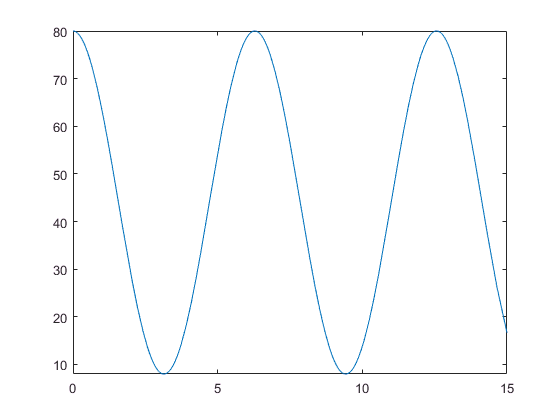

Vo = 80

Vo =    63.4509   29.0187    8.3603


Vo = 63.4509

Vo = 29.0187

Vo = 8.3603

fplot(@V, [0 15]);

Hit it: solve the equation.

[tt,y]=ode45(@(t,y)pi*D.^4/128/mu/L * (atm - y*R*T/V(t)) ,[0 15], double([atm*V(0)/R/T]));

Vo =    80.0000   71.9514   51.4045   27.5468   11.0459    9.2803   23.0394   46.1709   68.3316   79.6127   74.9697   56.4789   32.4082   13.5207    8.2618   18.9831   40.8905   64.1883   78.4590   77.3217   61.2847   37.5190   16.6512


Vo =    78.2528   62.2630   39.4286   16.9345    8.0213   14.2146   33.5761   59.3542   76.2096   79.1940   67.1382   44.4674   21.2992    8.6678   11.6742   29.1514   53.0700   73.5138   79.9825   70.4410   52.6790   26.2502


Vo =    79.5605   75.6391   67.4801   57.0050   45.4366   33.3271   21.8500   13.6363    8.9022    8.2443   11.3064   18.2267   28.0947   39.8079   52.9234   64.0706   72.7497   78.3394   79.9809   77.5180   71.4444   62.0753   50.5684   38.3560   26.5808   17.0497   10.5285    8.0235    9.4848   14.8923   23.7702   34.8906   47.0241   58.8439   69.2725   76.3900   79.6905   79.2115   74.3658   66.1530   57.0900   45.1242   31.7131   21.1065


Vo =    79.8900   79.0137   77.0866   73.9225   69.8185   64.9550   59.6857   54.2385   36.3490   30.3856   24.6127   19.2831   15.2014   12.2485    9.8200    8.3008    8.0304    8.6617   10.1791   12.6546   16.1122   20.5418   25.5050   30.7911   36.6633   49.5723   56.1939   61.7629   66.2643   70.6519   74.6074   77.3787   79.0856   79.9413   79.7311   78.4683   76.3493   73.3115   69.3817   64.6832   59.3338   53.5583   35.3507   29.4374   23.8610   19.0911   15.1888   11.8886    9.4518    8.2358


Vo =    79.9725   79.7526   79.3141   78.6597   77.7056   76.3973   74.8135   72.9677   70.9117   68.6739   66.2397   63.6285   60.9884   58.3572   28.9520   26.0599   23.2084   20.5406   18.0802   16.0476   14.3973   12.9197   11.6236   10.3951    9.3220    8.5615    8.1206    8.0002    8.1118    8.4277    8.9461    9.7007   10.7146   11.9534   13.4087   15.1353   17.1433   19.3603   21.7690   24.2556   26.7854   29.4307   57.7896   60.5703   62.9302   65.1825   67.3146   69.5184   71.7298   73.7096


Vo =    79.9931   79.9381   79.8281   79.6634   79.4441   79.1706   78.8434   78.4629   77.9882   77.4050   76.7507   76.0267   75.2346   74.3761   73.4529   72.4671   71.4384   11.3288   10.7111   10.0980    9.5613    9.1022    8.7219    8.4211    8.2006    8.0608    8.0043    8.0089    8.0647    8.1717    8.3296    8.5384    8.7976    9.1070    9.4832    9.9327   10.4398   11.0036   11.6231   12.2973   13.0251   13.8053   14.6678   15.6168   71.1979   72.2471   73.2373   74.1664   75.0325   75.8338


Vo =    79.9983   79.9845   79.9570   79.9157   79.8608    8.1580    8.0881    8.0385    8.0112    8.0007    8.0029    8.0180    8.0460    8.0867    8.1401   79.8518   79.9160   79.9621   79.9901   80.0000   79.9918   79.9655   79.9211   79.8586    8.1303    8.0772    8.0379    8.0125    8.0008    8.0030    8.0190    8.0488    8.0924    8.1499   79.8835   79.9348   79.9714   79.9931   80.0000   79.9920   79.9677   79.9248   79.8640


Vo =    79.9996   79.9961   79.9892   79.9789   79.9652   79.9480    8.0738    8.0490    8.0292    8.0158    8.0074    8.0021    8.0000    8.0012    8.0055    8.0131    8.0238    8.0378    8.0549   79.9292   79.9523   79.9708   79.9848   79.9943   79.9992   79.9996   79.9955   79.9869   79.9737   79.9561   79.9339    8.0465    8.0303    8.0175    8.0083    8.0024    8.0001    8.0011    8.0057    8.0137    8.0251    8.0401    8.0584   79.9454   79.9636   79.9782   79.9891   79.9962   79.9997   79.9994


Vo =    79.9999   79.9990   79.9973   79.9947   79.9913   79.9870    8.0134    8.0092    8.0057    8.0031    8.0013    8.0002    8.0000    8.0006    8.0020    8.0041    8.0071    8.0109   79.9817   79.9876   79.9923   79.9959   79.9984   79.9997   79.9999   79.9990   79.9970   79.9938   79.9895   79.9840    8.0149    8.0103    8.0065    8.0036    8.0015    8.0003    8.0000    8.0006    8.0020    8.0042    8.0074    8.0114   79.9867   79.9912   79.9948   79.9974   79.9991   79.9999   79.9998   79.9987


Vo =    80.0000   71.9514   51.4045   27.5468   11.0459    9.2803   23.0394   46.1709   68.3316   79.6127   74.9697   56.4789   32.4082   13.5207    8.2618   18.9831   40.8905   64.1883   78.4590   77.3217   61.2847   37.5190   16.6512


Vo =    78.2528   62.2630   39.4286   16.9345    8.0213   14.2146   33.5761   59.3542   76.2096   79.1940   67.1382   44.4674   21.2992    8.6678   11.6742   29.1514   53.0700   73.5138   79.9825   70.4410   52.6790   26.2502


Vo =    79.5605   75.6391   67.4801   57.0050   21.8500   13.6363    8.9022    8.2443   11.3064   18.2267   28.0947   64.0706   72.7497   78.3394   79.9809   77.5180   71.4444   62.0753   26.5808   17.0497   10.5285    8.0235    9.4848   14.8923   23.7702   58.8439   69.2725   76.3900   79.6905   79.2115   74.3658   66.1530


Vo =    79.8900   79.0137   77.0866   73.9225   12.2485    9.8200    8.3008    8.0304    8.6617   10.1791   12.6546   74.6074   77.3787   79.0856   79.9413   79.7311   78.4683   76.3493   11.8886    9.4518    8.2358    8.0322    8.7497   10.4619   13.1675   75.0488   77.5291   79.1907   79.9550   79.7392   78.4035   75.9715


Vo =    79.9725   79.7526   79.3141   78.6597   77.7056   10.3951    9.3220    8.5615    8.1206    8.0002    8.1118    8.4277    8.9461    9.7007   10.7146   77.8855   78.7396   79.3768   79.8130   79.9973   79.8921   79.4983   78.8596   78.0209   11.1738    9.9541    9.0228    8.4244    8.1021    8.0002    8.1194    8.4746    9.0866    9.9435   78.0206   78.8536   79.4698   79.8523   79.9984   79.8966   79.5107   78.8422   77.8963


Vo =    79.9931   79.9381   79.8281   79.6634   79.4441   79.1706    9.1022    8.7219    8.4211    8.2006    8.0608    8.0043    8.0089    8.0647    8.1717    8.3296    8.5384    8.7976   79.2381   79.5017   79.7218   79.8862   79.9783   79.9981   79.9455   79.8206   79.6236   79.3550   79.0339    9.2281    8.8360    8.5393    8.3233    8.1620    8.0559    8.0049    8.0093    8.0689    8.1837    8.3604    8.6044    8.9105   79.0294   79.3376   79.5875   79.7787   79.9110   79.9841   79.9979   79.9485


Vo =    79.9983   79.9845   79.9570   79.9157   79.8608    8.3584    8.2482    8.1580    8.0881    8.0385    8.0112    8.0007    8.0029    8.0180    8.0460    8.0867    8.1401   79.7697   79.8518   79.9160   79.9621   79.9901   80.0000   79.9918   79.9655   79.9211   79.8586   79.7781    8.1972    8.1303    8.0772    8.0379    8.0125    8.0008    8.0030    8.0190    8.0488    8.0924    8.1499   79.8174   79.8835   79.9348   79.9714   79.9931   80.0000   79.9920   79.9677   79.9248   79.8640   79.7853


Vo =    80.0000   71.9514   51.4045   27.5468   11.0459    9.2803   23.0394   46.1709   68.3316   79.6127   74.9697   56.4789   32.4082   13.5207    8.2618   18.9831   40.8905   64.1883   78.4590   77.3217   61.2847   37.5190   16.6512


Vo =    78.2528   62.2630   39.4286   16.9345    8.0213   14.2146   33.5761   59.3542   76.2096   79.1940   67.1382   44.4674   21.2992    8.6678   11.6742   29.1514   53.0700   73.5138   79.9825   70.4410   52.6790   26.2502


Vo =    79.5605   75.6391   67.4801   57.0050   21.8500   13.6363    8.9022    8.2443   11.3064   18.2267   28.0947   64.0706   72.7497   78.3394   79.9809   77.5180   71.4444   62.0753   26.5808   17.0497   10.5285    8.0235    9.4848   14.8923   23.7702   58.8439   69.2725   76.3900   79.6905   79.2115   74.3658   66.1530


Vo =    79.8900   79.0137   77.0866   73.9225   12.2485    9.8200    8.3008    8.0304    8.6617   10.1791   12.6546   74.6074   77.3787   79.0856   79.9413   79.7311   78.4683   76.3493   11.8886    9.4518    8.2358    8.0322    8.7497   10.4619   13.1675   75.0488   77.5291   79.1907   79.9550   79.7392   78.4035   75.9715


Vo =    79.9725   79.7526   79.3141   78.6597   77.7056   10.3951    9.3220    8.5615    8.1206    8.0002    8.1118    8.4277    8.9461    9.7007   10.7146   77.8855   78.7396   79.3768   79.8130   79.9973   79.8921   79.4983   78.8596   78.0209   11.1738    9.9541    9.0228    8.4244    8.1021    8.0002    8.1194    8.4746    9.0866    9.9435   78.0206   78.8536   79.4698   79.8523   79.9984   79.8966   79.5107   78.8422   77.8963


Vo =    79.9931   79.9381   79.8281   79.6634   79.4441   79.1706    9.1022    8.7219    8.4211    8.2006    8.0608    8.0043    8.0089    8.0647    8.1717    8.3296    8.5384    8.7976   79.2381   79.5017   79.7218   79.8862   79.9783   79.9981   79.9455   79.8206   79.6236   79.3550   79.0339    9.2281    8.8360    8.5393    8.3233    8.1620    8.0559    8.0049    8.0093    8.0689    8.1837    8.3604    8.6044    8.9105   79.0294   79.3376   79.5875   79.7787   79.9110   79.9841   79.9979   79.9485


Vo =    79.9983   79.9845   79.9570   79.9157   79.8608    8.3584    8.2482    8.1580    8.0881    8.0385    8.0112    8.0007    8.0029    8.0180    8.0460    8.0867    8.1401   79.7697   79.8518   79.9160   79.9621   79.9901   80.0000   79.9918   79.9655   79.9211   79.8586   79.7781    8.1972    8.1303    8.0772    8.0379    8.0125    8.0008    8.0030    8.0190    8.0488    8.0924    8.1499   79.8174   79.8835   79.9348   79.9714   79.9931   80.0000   79.9920   79.9677   79.9248   79.8640   79.7853


Vo = 80

Vo = 80

Vo = 78.3921

Vo = 76.4161

Vo = 57.0449

Vo = 52.4686

Vo = 46.5465

Vo = 46.5465

Vo = 35.8207

Vo = 30.6735

Vo = 11.4534

Vo = 9.6969

Vo = 8.3603

Vo = 8.3603

Vo = 43.2461

Vo = 41.5966

Vo = 33.4935

Vo = 32.0987

Vo = 30.3833

Vo = 30.3833

Vo = 27.3876

Vo = 25.9407

Vo = 19.3336

Vo = 18.2852

Vo = 17.0351

Vo = 17.0351

Vo = 14.3959

Vo = 13.2310

Vo = 9.1062

Vo = 8.6871

Vo = 8.3020

Vo = 8.3020

Vo = 14.9889

Vo = 14.0539

Vo = 10.3335

Vo = 9.8478

Vo = 9.3185

Vo = 9.3185

Vo = 8.5877

Vo = 8.3308

Vo = 8.1480

Vo = 8.3082

Vo = 8.5897

Vo = 8.5897

Vo = 8.9050

Vo = 8.7270

Vo = 8.1280

Vo = 8.0727

Vo = 8.0254

Vo = 8.0254

Vo = 8.0015

Vo = 8.0192

Vo = 8.4020

Vo = 8.5212

Vo = 8.6919

Vo = 8.6919

Vo = 9.0476

Vo = 9.2526

Vo = 10.5446

Vo = 10.8201

Vo = 11.1835

Vo = 11.1835

Vo = 12.0933

Vo = 12.5884

Vo = 15.4484

Vo = 16.0211

Vo = 16.7629

Vo = 16.7629

Vo = 19.0448

Vo = 20.2665

Vo = 27.0753

Vo = 28.3906

Vo = 30.0713

Vo = 30.0713

Vo = 36.5294

Vo = 39.8721

Vo = 56.5364

Vo = 59.3126

Vo = 62.6300

Vo = 62.6300

Vo = 70.9013

Vo = 74.1743

Vo = 79.4618

Vo = 78.3226

Vo = 76.0452

Vo = 76.0452

Vo = 69.7662

Vo = 65.7197

Vo = 40.3224

Vo = 35.5943

Vo = 29.9036

Vo = 29.9036

Vo = 72.5921

Vo = 70.5111

Vo = 57.2839

Vo = 54.5685

Vo = 51.0814

Vo = 51.0814

Vo = 44.6502

Vo = 41.4137

Vo = 26.0580

Vo = 23.6221

Vo = 20.7621

Vo = 20.7621

Vo = 46.1748

Vo = 43.7002

Vo = 31.5814

Vo = 29.5402

Vo = 27.0655

Vo = 27.0655

Vo = 22.8696

Vo = 20.9166

Vo = 12.9545

Vo = 11.8990

Vo = 10.7487

Vo = 10.7487

Vo = 24.3533

Vo = 23.0523

Vo = 17.1962

Vo = 16.2818

Vo = 15.1980

Vo = 15.1980

Vo = 13.4203

Vo = 12.6184

Vo = 9.5373

Vo = 9.1586

Vo = 8.7594

Vo = 8.7594

Vo = 8.1959

Vo = 8.0519

Vo = 8.7161

Vo = 9.0738

Vo = 9.6205

Vo = 9.6205

Vo = 8.4482

Vo = 8.3231

Vo = 8.0038

Vo = 8.0008

Vo = 8.0199

Vo = 8.0199

Vo = 8.1181

Vo = 8.1980

Vo = 8.9027

Vo = 9.0808

Vo = 9.3256

Vo = 9.3256

Vo = 9.8331

Vo = 10.1167

Vo = 11.8275

Vo = 12.1815

Vo = 12.6445

Vo = 12.6445

Vo = 13.9013

Vo = 14.5809

Vo = 18.4592

Vo = 19.2272

Vo = 20.2182

Vo = 20.2182

Vo = 23.4853

Vo = 25.2239

Vo = 34.7301

Vo = 36.5241

Vo = 38.7935

Vo = 38.7935

Vo = 48.1469

Vo = 52.7578

Vo = 72.1368

Vo = 74.5433

Vo = 76.9728

Vo = 76.9728

Vo = 79.7703

Vo = 79.9754

Vo = 69.4157

Vo = 65.8007

Vo = 60.7460

Vo = 60.7460

Vo = 51.6626

Vo = 46.8707

Vo = 23.8664

Vo = 20.4466

Vo = 16.6512

Vo = 16.6512

Vo = 56.4673

Vo = 54.2442

Vo = 42.6718

Vo = 40.5937

Vo = 38.0129

Vo = 38.0129

Vo = 33.1471

Vo = 30.7871

Vo = 20.1626

Vo = 18.5409

Vo = 16.6512

Vo = 16.6512

The plotting section.

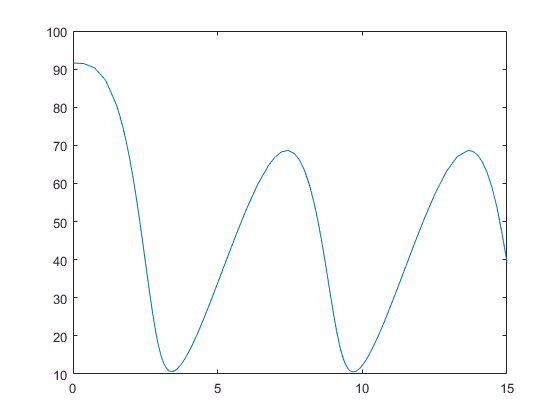

figure(2)
clf
plot(tt, y)

figure(3)
clf
hold on
PP=y/V(tt)*R*T;

Vo =    80.0000
   77.4983
   70.3408
   59.5224
   46.5465
   42.4209
   38.3161
   34.2859
   30.3833
   26.6596


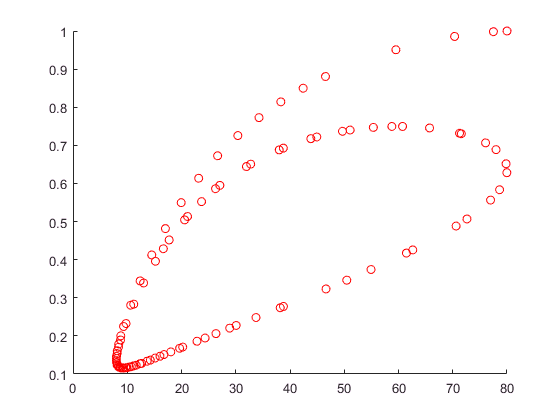

Vo = 80

Vo = 77.4983

Vo = 70.3408

Vo = 59.5224

Vo = 46.5465

Vo = 42.4209

Vo = 38.3161

Vo = 34.2859

Vo = 30.3833

Vo = 26.6596

Vo = 23.1636

Vo = 19.9414

Vo = 17.0351

Vo = 14.5139

Vo = 12.3699

Vo = 10.6307

Vo = 9.3185

Vo = 8.8136

Vo = 8.4289

Vo = 8.1659

Vo = 8.0254

Vo = 8.0079

Vo = 8.1134

Vo = 8.3417

Vo = 8.6919

Vo = 9.1479

Vo = 9.7164

Vo = 10.3957

Vo = 11.1835

Vo = 12.3376

Vo = 13.6569

Vo = 15.1346

Vo = 16.7629

Vo = 19.6492

Vo = 22.8584

Vo = 26.3478

Vo = 30.0713

Vo = 38.1943

Vo = 46.6373

Vo = 54.9350

Vo = 62.6300

Vo = 72.6183

Vo = 78.6290

Vo = 79.8268

Vo = 76.0452

Vo = 71.5795

Vo = 65.7245

Vo = 58.7751

Vo = 51.0814

Vo = 44.9381

Vo = 38.7671

Vo = 32.7504

Vo = 27.0655

Vo = 23.6979

Vo = 20.5731

Vo = 17.7285

Vo = 15.1980

Vo = 13.0119

Vo = 11.1965

Vo = 9.7733

Vo = 8.7594

Vo = 8.3831

Vo = 8.1339

Vo = 8.0127

Vo = 8.0199

Vo = 8.1555

Vo = 8.4190

Vo = 8.8095

Vo = 9.3256

Vo = 9.9724

Vo = 10.7431

Vo = 11.6349

Vo = 12.6445

Vo = 14.2369

Vo = 16.0387

Vo = 18.0371

Vo = 20.2182

Vo = 24.3464

Vo = 28.8822

Vo = 33.7314

Vo = 38.7935

Vo = 50.4661

Vo = 61.4586

Vo = 70.6152

Vo = 76.9728

Vo = 79.9740

Vo = 77.9753

Vo = 71.2546

Vo = 60.7460

Vo = 55.3618

Vo = 49.6775

Vo = 43.8431

Vo = 38.0129

Vo = 31.9598

Vo = 26.2700

Vo = 21.1153

Vo = 16.6512

for i=1:size(tt,1)
plot(V(tt(i)),PP(i)/atm,'ro');
end

Define function V(t)

function Vo=V(t)
    Vo=(8+36+36*sin(t+pi/2))
end